## Set up

clc
clear
clf
rng(16);

Preprocessing

SmarketD = readtable("Data\Smarket.csv");
SmarketD.Direction = categorical(SmarketD.Direction);
summary(SmarketD);

Variables:

    Var1: 1250×1 double

        Values:

            Min            1  
            Median     625.5  
            Max         1250  

    Year: 1250×1 double

        Values:

            Min         2001  
            Median      2003  
            Max         2005  

    Lag1: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag2: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag3: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag4: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag5: 1250×1 double

        Values:

           

Smarket = normalize(SmarketD(:,3:end-1));
Smarket.Direction = SmarketD.Direction;

train = (SmarketD.Year < 2005);
Smarket2005 = Smarket(~train,:);
Direction2005 = SmarketD.Direction(~train,:);
Direction = SmarketD.Direction;

% corrplot(Smarket(:,1:end-1));

k_values = 1:100;
cv_accuracies = zeros(1,length(k_values));
k_fold = 10;
cv = cvpartition(length(Smarket.Direction), 'KFold', k_fold);

for i = 1:length(k_values)
    k = k_values(i);
    accuracies = zeros(1, k_fold);
    
    for fold = 1:k_fold
        trn = training(cv, fold);
        tst = test(cv, fold);
        
        X_train = Smarket(trn, 1:2);
        y_train = Smarket.Direction(trn);
        X_test = Smarket(tst, 1:2);
        y_test = Smarket.Direction(tst);
        
        % Train kNN for current k
        kNN_model = fitcknn(X_train, y_train, 'NumNeighbors', k);
        
        y_pred = predict(kNN_model, X_test);
        
        accuracy = sum(y_pred == y_test) / length(y_test);
        accuracies(fold) = accuracy;
        
    end
    
    cv_accuracies(i) = mean(accuracies);
end
[M, I] = max(cv_accuracies);
best_k = k_values(I);

disp(['Best k: ', num2str(best_k)]);

Best k: 37


disp(['Cross validation accuracy with best k: ', num2str(M)]);

Cross validation accuracy with best k: 0.5272


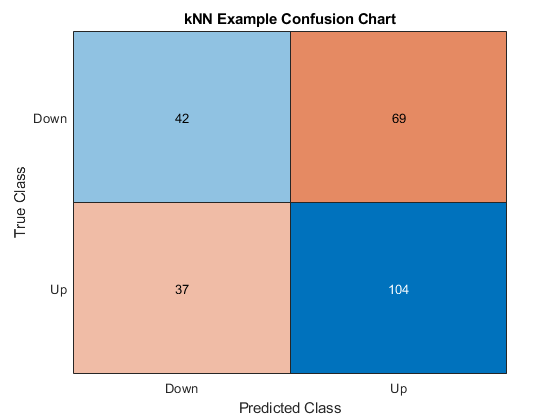


final_kNN_model = fitcknn(Smarket(:,1:2),Smarket.Direction, 'NumNeighbors', best_k);
% plot(1:100, correction_rate)
% title('kNN correction rate');
% xlabel('Correction rate');
% ylabel('Number of neighbours');

y_pred = predict(final_kNN_model, Smarket2005);
C = confusionmat(Direction2005, y_pred);
confusionchart(Direction2005, y_pred);
title('kNN Example Confusion Chart');
print('Results/Example/kNN/kNN_confchart_2', '-dpng', '-r600')

disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    42    69
    37   104



correction_rate = sum(diag(C))/sum(C,"all");




% kNN_reduced = fitcdiscr(Smarket_reduced(train, :), Direction(train));
% 
% gscatter(Smarket_reduced(train, 1), Smarket_reduced(train, 2), Direction(train), 'rb');
% title('LDA Dimensionality Reduction of Smarket (Training)');
% xlabel('LDA Component 1');
% ylabel('LDA Component 2');
% legend('Up', 'Down', 'Location', 'best');
% 
% % [L, W] = meshgrid(linspace(-5, 5, 500), linspace(-5,5,100)); ...
% % L = L(:);
% % W = W(:);
% % pred = lda_reduced.predict([L W]);
% % hold on;
% % h = gscatter(L, W, pred, 'rb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
% % hold off; 
% 
% y_pred = predict(lda_reduced, Smarket2005_reduced);
% C = confusionmat(Direction2005, y_pred);
% disp('Confusion Matrix:');
% disp(C);

#### Prior probabilities

array2table(ldafit.Prior, 'VariableNames', cellstr(ldafit.ClassNames))

Unable to resolve the name ldafit.Prior.

Group means

% array2table(ldafit.Mu, 'VariableNames',cellstr(ldafit.ClassNames))

Predictions

[ldaPredClass, ldaPredPosterior] = predict(kNN_model_LDA,Smarket2005_reduced);
confusionchart(ldaPredClass, Direction2005)
mean(ldaPredClass == Direction2005)

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)
sum(ldaPredPosterior(:,1) < 0.5)
ldaPredPosterior(1:20,1).'
ldaPredClass(1:20,1).'

% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)


